# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Metoda Richardsona - programowe sterowanie zbieżnością

**ĆWICZENIE 1**

Parametr *p* w metodzie Richardsona służy programowemu wpływaniu na szybkość zbieżności metody.

Uruchom ten skrypt kilka razy i zauważ:

- zależność miedzy promieniem spektralnym a parametrem p i szybkością zbieżności

- fakt, że za każdym razem szybkość zbieżności jest trochę inna - to wpływ losowego punktu startowego, który też ma znaczenie przy określaniu zbieżności (ilości iteracji) - ustaw punkt bardzo odległy od rozwiązania np. x100 i zobacz co się dzieje

p = 0.0100

Promień spektralny macierzy M: 0.91


p = 0.0600

Promień spektralny macierzy M: 0.47


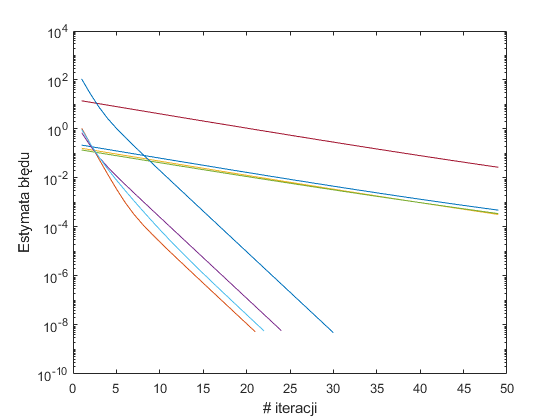

%Czyszczenie
clear all;clc;

% Najpierw zdefiniujmy przykładowy układ równań:
A=wilkinson(5)+10*eye(5);
b=sum(A,2);

%wektor warości parametru p, dla którego chcemy rozwiązać układ:
p_vect = [0.01 0.06]

for p=p_vect
    % Dokonajmy teraz rozkładu macierzy A wg schematu metody Richardsona
    % uzyskując macierz M i wektor w
    p
    M=eye(size(A,1))-p*A;
    w=p*b;
    
    spectrumM = abs(max(eig(M)));
    
    %Przyjęcie parametrów dla algorytmu iteracyjengo 
    
    %-> punkt startowy - losowy
    x0=rand(numel(b),1);
    %x0=100*rand(numel(b),1);
    
    %-> wymagana dokładność
    delta0 = 1e-8;
    
    %-> maksymalna ilość iteracji
    i_max = 50;
    
    %Implementacja metody Richardsona
    i=1;     %licznik iteracji 
    error=5*delta0;
    x_old=x0;
    x=x_old; %wektor rozwiązań w kolejnych iteracjach;
    n=i;     %wektor numerów iteracji do rysowania
    err = [];%wektor błędów do rysowania
    while( (error>=delta0) & (i<i_max))
        x_new = M*x(:,end)+w;
        error = norm(x_new-x_old);  %obliczenie esymaty błędu
        x_old=x_new;
        x=[x x_new]; 
        
        err=[err error];  
        n=[n i];i = i+1;
        
    end
    
    %Rysowanie błędu
    %hold off;
    fprintf("Promień spektralny macierzy M: %0.2f\n", spectrumM);
    semilogy(n, [err(1) err]);xlabel("# iteracji");ylabel("Estymata błędu");
    hold on;
end

**ĆWICZENIE 2**

Dobór optymalnego p jest problemem nie do końca rozwiązanym. Znamy metody doboru optymalnego p dla niektórych istotnych układów równań (macierzy A) np.:

Jeżeli macierz **A** ma rzeczywiste wartości własne tego samego znaku (jest np. macierzą symetryczną dodatnio określoną), to promień spektralny macierzy  jest  najmniejszy, gdy:

albo - dla macierzy symetrycznych promień spektralny można wyrazić przez wskaźnik uwarunkowania macierzy **A**:

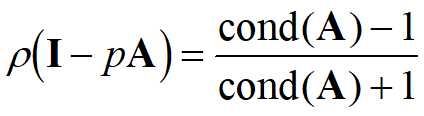

- Spróbuj pobawić się wartościami parametru p tak, żeby dobrać wartość optymalną